## **Driver test program to check Clothoids library**

**Biarcs**

Plot a family o biarcs

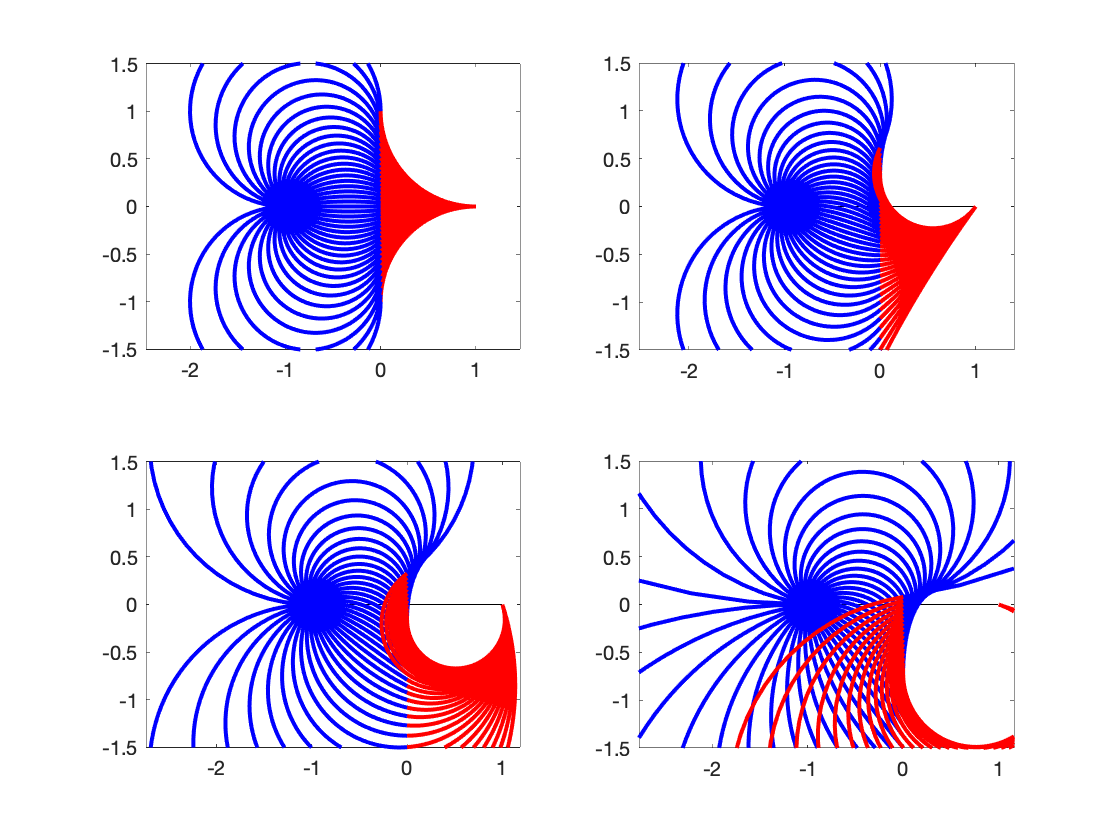

x0 = -1; y0 = 0; x1 = 1; y1 = 0; kk = 1;

thmin = 0;
thmax = 0.9*pi;
for theta1=thmin:(thmax-thmin)/3:thmax
  subplot(2,2,kk);
  hold off
  plot([x0,x1],[y0,y1],'k');
  xlim([-1.5,1.5]);
  ylim([-1.5,1.5]);
  axis([-1.5,1.5,-1.5,1.5]);
  hold on
  for theta0=[-pi:pi/20:pi]
    L1 = Biarc(x0,y0,theta0,x1,y1,theta1);
    L1.plot();
  end
  axis equal
  kk = kk+1;
end